# Exergy Analysis Demo

Use `ExergyAnalysis` function to obtain the exergy balances and Table FP for an state of the plant

### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(file);
if ~isValid(data)
    return
end

### Select the state of the plant to analyze

states=string(data.StateNames);
state=char(states(2));

### Get Exergy Analysis

Use function `ExergyAnalysis `to get the results of the selected states

res=ExergyAnalysis(data,'State',state)

res =   cResultInfo with properties:

          Tables: [1×1 struct]
      NrOfTables: 4
            Info: [1×1 cExergyModel]
         ClassId: 1
        ResultId: 2
      ResultName: 'Exergy Analysis'
       ModelName: 'cgam_model'
           State: 'T1180'
          Sample: ''
    DefaultGraph: 'tfp'
          status: 1
        objectId: 1749606515


**List the available tables**

ListResultTables(res);


Exergy Analysis - Table Index

 Key          Description                      Graph  
————————————————————————————————————————————————————————
 eflows       Flows Exergy Table               false  
 estreams     Productive Groups Exergy Table   false  
 eprocesses   Processes Exergy Table           false  
 tfp          FP Table                         true   



Show all results tables using `ShowResults` function

ShowResults(res);


Flows Exergy Table - T1180

Key  From     To              B(MW)
————————————————————————————————————
NG   ENV_R1   COMB_F1        73.327
B1   ENV_R2   CMP_P1          0.000
B2   CMP_P1   APH_P1         29.507
B3   APH_P1   COMB_F1        50.896
B4   COMB_P1  TRB_F1        103.462
B5   TRB_F1   APH_F1         38.735
B6   APH_F1   HRSG_F1        15.021
B7   HRSG_F1  STCK_F1         2.230
WC   TRB_P1   CMP_F1         32.033
WN   TRB_P1   ENV_O1         30.000
QV   HRSG_P1  ENV_O2          9.403
QG   STCK_P1  ENV_W1          2.230


Productive Groups Exergy Table - T1180

Key             E(MW)      ET(MW)
——————————————————————————————————
COMB_F1       124.223     124.223
COMB_P1       103.462     103.462
CMP_F1         32.033      32.033
CMP_P1         29.507      29.507
TRB_F1         64.727     103.462
TRB_P1         62.033      62.033
APH_F1         23.714      38.735
APH_P1         21.389      50.896
HRSG_F1        12.791      15.021
HRSG_P1         9.403       9.403
STCK_F1        

### Show the Diagram FP

Show the diagram FP using the `ShowGraph, tfp `is the default graph of this `cResultInfo`

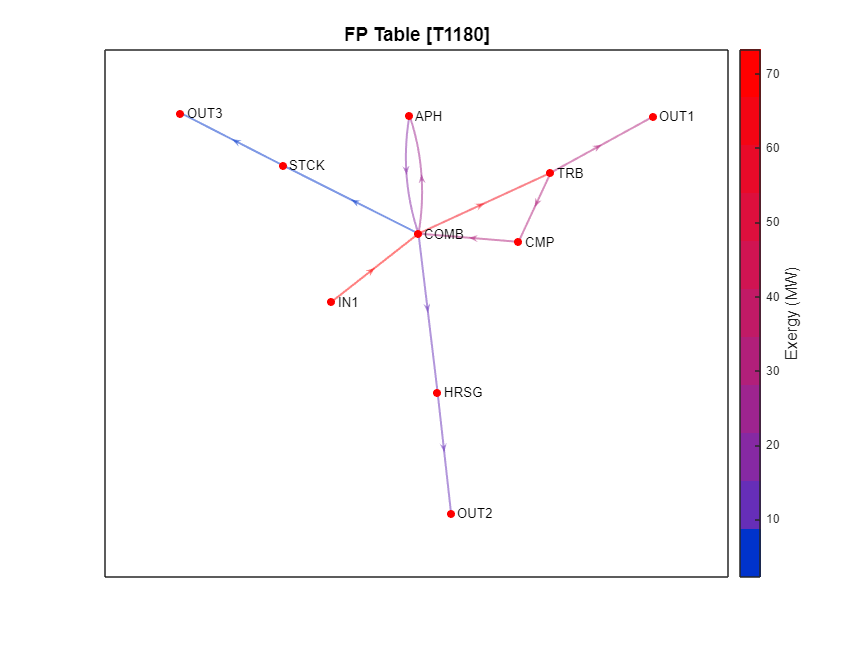

ShowGraph(res);

### Save the Results

Save the results using the function `SaveResults`

save = false;
if save
    SaveResults(res,'cgam_exergy.xlsx');
end

### Additional Help Information

help ExergyAnalysis

 ExergyAnalysis - Perform exergy analysis of a system for a specific plant operating state.
    Analyzes a thermoeconomic data model using the Second Law of Thermodynamics, 
    to calculate the irreversibilities and efficiencies for all processes of the model. 
    This analysis step quantifies the energy quality degradation and process performance.
 
    This function required a data model, including the exergy values for all system flows to calculate:
      - The exergy of fuel and products of each process.
      - The irreversibilities (exergy destruction)
      - The unit consumption and exergetic efficiency
      - The Fuel-Product tables showing the processes relationships
 
    Syntax:
      res = ExergyAnalysis(data)
      res = ExergyAnalysis(data, Name, Value)
 
    Input Arguments:
      data - Data model containing plant structure and thermodynamic states
        cDataModel object
 
    Name-Value Arguments:
      State - 